# Hierarchy Reconstruct

### `Matlab script to reconstruct the hierarchy between nodes of dynamical river networks and plot the status of unobserved nodes.`

#### `Credits: Nicola Durighetto et al., Faye Delacrétaz`

#### `SIE Project Autumn 2023`

Clearing and loading

% Clear the MATLAB workspace, close all figures, and clear the command window.
% This ensures a clean start for the script execution.
clear
close all
clc

% Import functions
import getHierarchy.*
import plotStatus.*
import plotHierarchyGraph.*

% Load network data from a specific file. Adjust the file name as needed.
% This file should contain the necessary data of our network
% We here used a CSV file to store our data
network_data = readtable('data_real.csv');

Restructure data and create necessary matrices

% Define node IDs, primarily used for plotting and visualization.
nodeId = network_data.ID;

% Define an array containing only the observations of the network
% This should be modified according to the CSV file
network_obs = table2array(network_data(:,4:end)); % the 3 first columns do not contain observation data


Define network hierarchy for different % of observed nodes

% Percentage of observed nodes (of values we want to keep in netword_data)
% For this test, we define the observation array for 100%, 75%, 50%, 25% and 10% of observed nodes in the network
%percentage_values = [1, 0.75, 0.5, 0.25, 0.1];
percentage_values = [1];
len_p = length(percentage_values);

% Define the k for the number of computation of our model
k = 10;

% Compute the necessary variables
[network_obs_p, statusObs_p, observationMatrix_p, hierarchyMatrix_p, hierarchyGraph_p, order_p, nodeId_p, network_data_p, hierarchyAccuracy_p, statusHierarchy_p, thresholdValue_p, thresholdUncertainty_p, nodewiseAccuracy_p, timewiseAccuracy_p, totalAccuracy_p] = getHierarchy_p(network_data, network_obs, nodeId, percentage_values, len_p, k);


Total accuracies for 100% of available observations:
Iteration #1: 0.99966
Iteration #2: 0.99966
Iteration #3: 0.99966
Iteration #4: 0.99966
Iteration #5: 0.99966
Iteration #6: 0.99966
Iteration #7: 0.99966
Iteration #8: 0.99966
Iteration #9: 0.99966
Iteration #10: 0.99966
Median accuracy: 0.99966
Iteration #1 has the accuracy value the closest to median_accuracy: 0.99966


### Plots

Results for 100% of available observations:


Hierarchy graph:

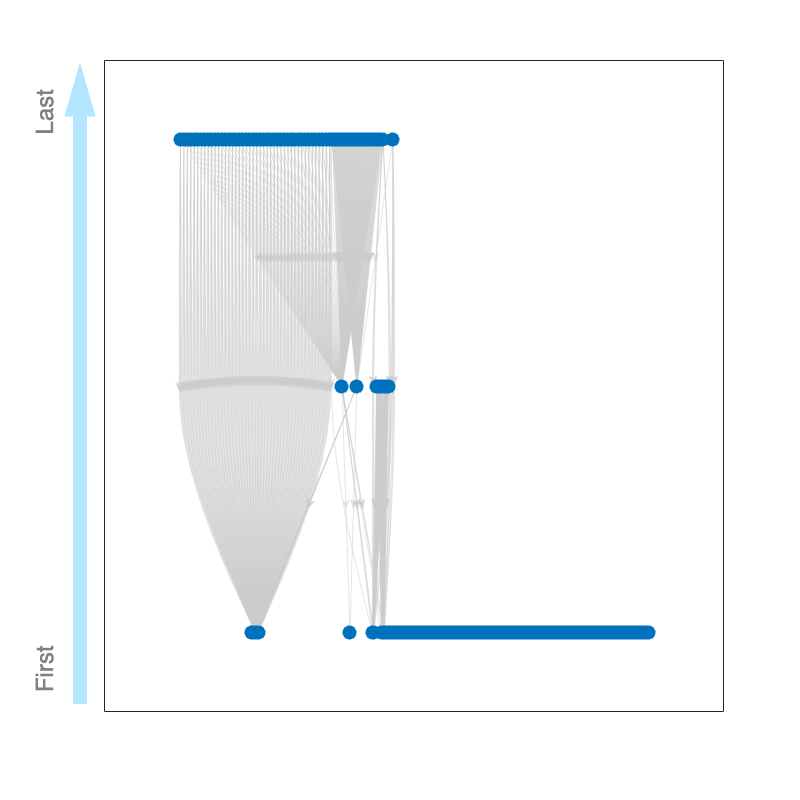

Confusion matrix:

Total accuracy: 0.99966


No False Positives found.
Nodes with False Negatives:
   198



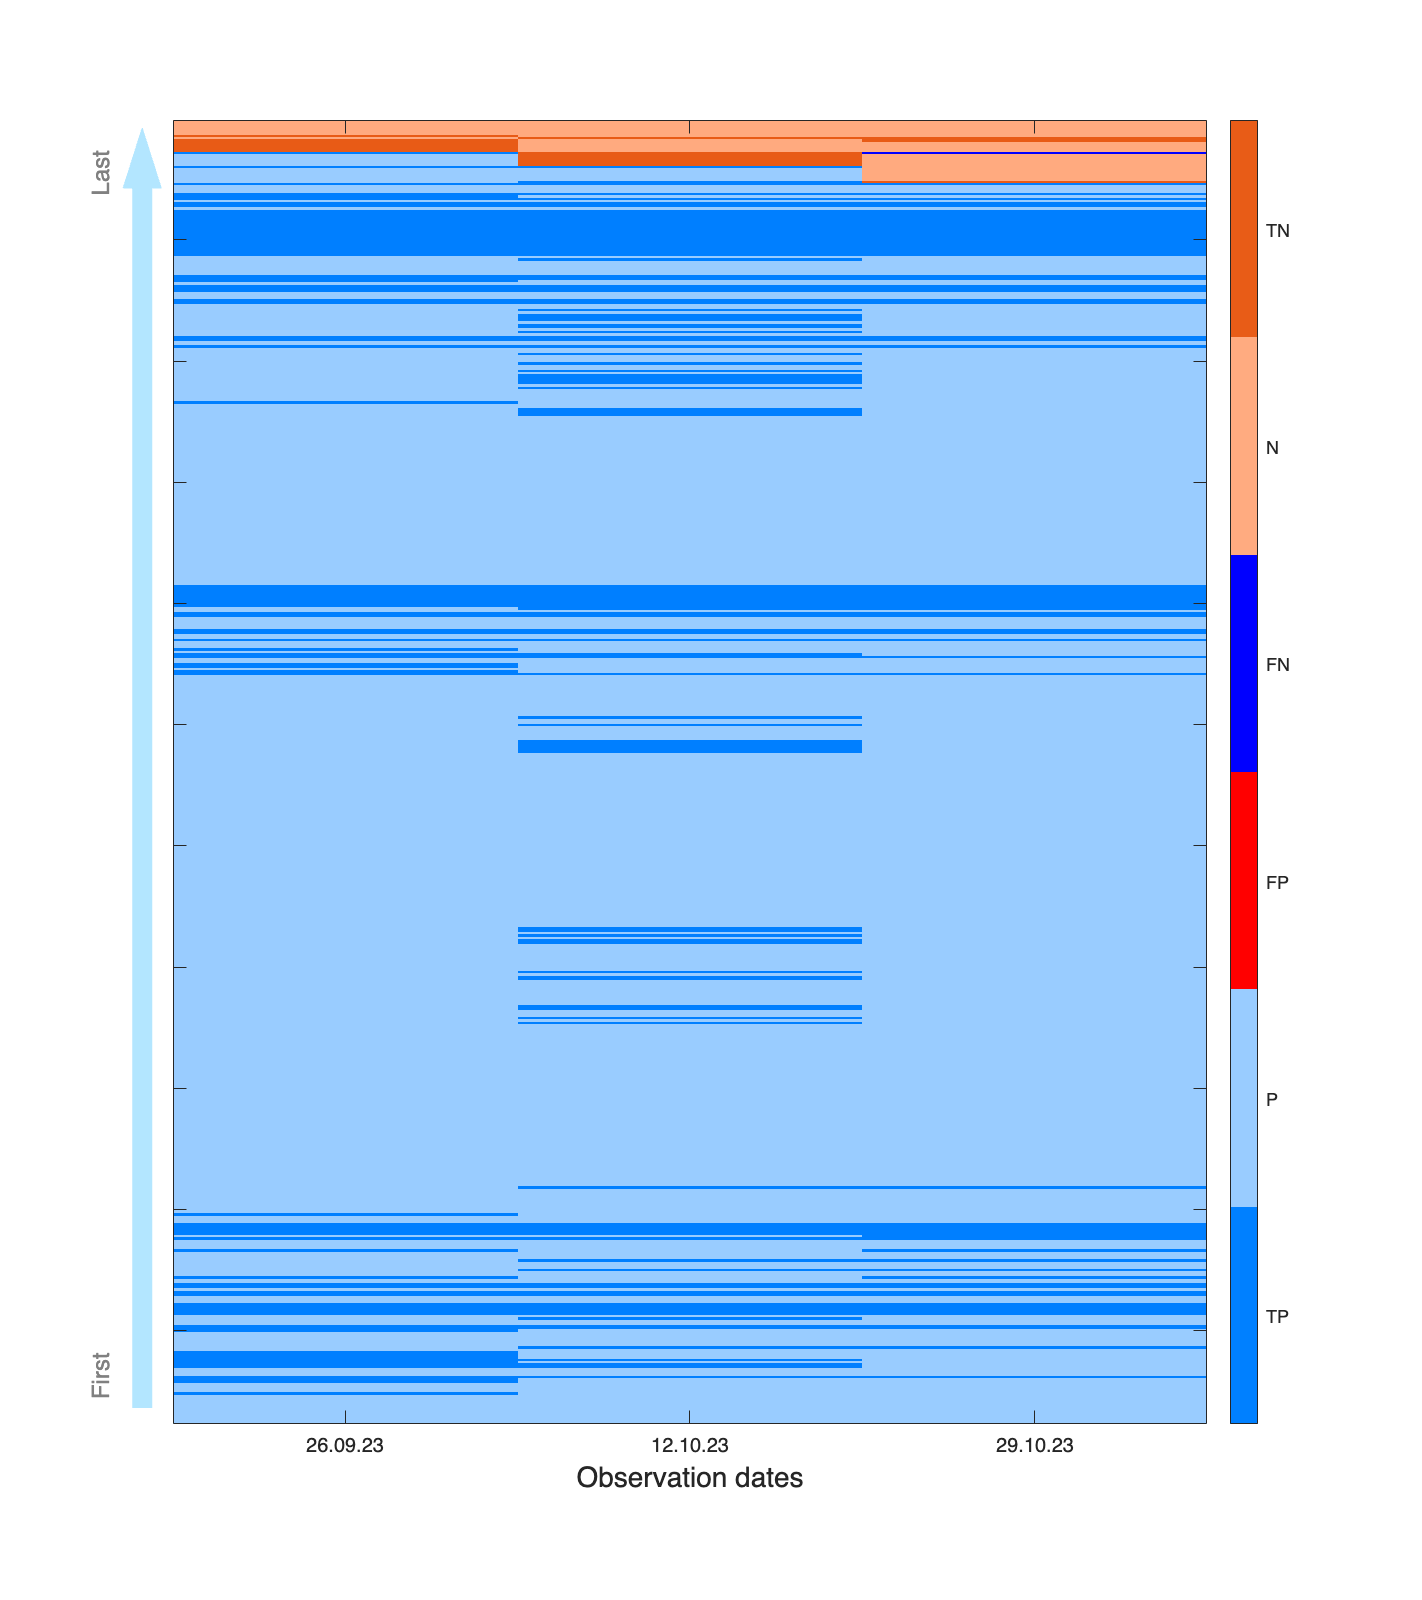

for i = 1:len_p
    fprintf('Results for %0.f%% of available observations:\n', percentage_values(i)*100)
    fprintf('Hierarchy graph:')
    plotHierarchyGraph(hierarchyGraph_p{i})
    fprintf('Confusion matrix:')
    fprintf('Total accuracy: %0.5f\n', totalAccuracy_p(i));
    plotStatus(network_data, nodeId_p(:,:,i), statusObs_p(:,:,i), statusHierarchy_p(:,:,i), thresholdValue_p(:,:,i), thresholdUncertainty_p(:,:,i));
end